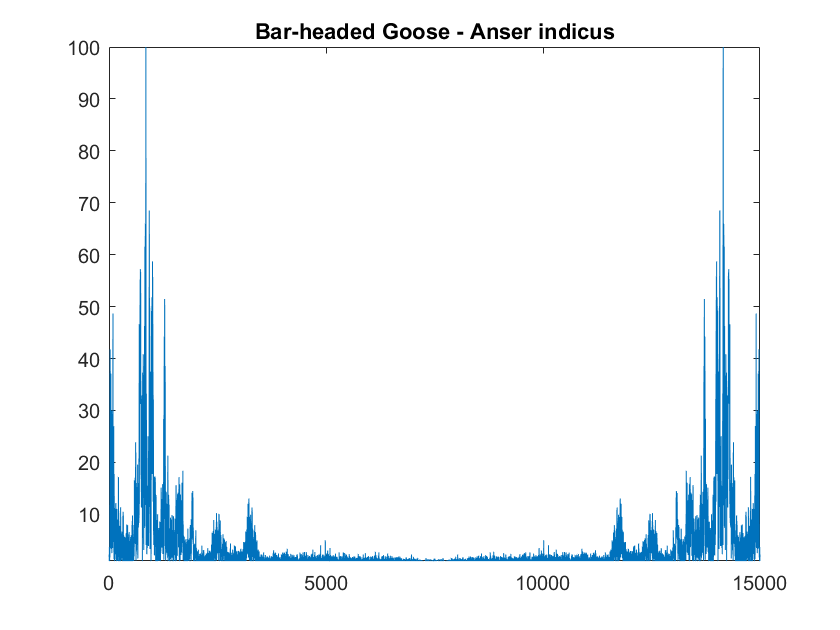

clc;clear; 
%DATA BASE SIGNALS
[ref1,fs1]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC431196 - Bar-headed Goose - Anser indicus.mp3');
[ref2,fs2]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\bat-noises.mp3');
[ref3,fs3]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\cow.mp3');
[ref4,fs4]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant.mp3');
[ref5,fs5]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot.wav');
[ref6,fs6]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\classic goat.mp3');
[ref7,fs7]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC369151 - Lesser Whistling Duck - Dendrocygna javanica.mp3');
[ref8,fs8]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC569023 - Snow Partridge - Lerwa lerwa.mp3');

%[ref5,fs5]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot_ref.aac');

%resample at 30,000 Hz sampling freq
fsc=30000; %fs_common
[P,Q] = rat(30000/fs1);
ref1 = resample(ref1,P,Q);
ref1=ref1(1:0.5*fsc,1);
%ref1=100*normalize(ref1,'range');

[P,Q] = rat(30000/fs2);
ref2 = resample(ref2,P,Q);
ref2=ref2(1:0.5*fsc,1);
%ref2=100*normalize(ref2,'range');

[P,Q] = rat(30000/fs3);
ref3 = resample(ref3,P,Q);
ref3=ref3(1:0.5*fsc,1);
%ref3=100*normalize(ref3,'range');

[P,Q] = rat(30000/fs4);
ref4 = resample(ref4,P,Q);
ref4=ref4(0.5*fsc:1*fsc,1);
%ref4=100*normalize(ref4,'range');

[P,Q] = rat(30000/fs5);
ref5 = resample(ref5,P,Q);
ref5=ref5(1:0.5*fsc,1);
%ref5=100*normalize(ref5,'range');

[P,Q] = rat(30000/fs6);
ref6 = resample(ref6,P,Q);
ref6=ref6(1:0.5*fsc,1);
%ref6=100*normalize(ref6,'range');

[P,Q] = rat(30000/fs7);
ref7 = resample(ref7,P,Q);
ref7=ref7(4.5*fsc:5*fsc,1);

[P,Q] = rat(30000/fs8);
ref8 = resample(ref8,P,Q);
ref8=ref8(2.2*fsc:2.7*fsc,1);

%doc fft
%doc audioread
%doc normalize
%sound(ref3);
%doc sgolayfilt
%doc findpeaks
%matrix=zeros(1,100);
%[y_in,fs]=audioread("C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC431196 - Bar-headed Goose - Anser indicus.mp3");

%TEST SIGNALS

[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC431197 - Bar-headed Goose - Anser indicus.mp3'); %take 0.5*fsc to 1*fsc
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC460220 - Bar-headed Goose - Anser indicus.mp3'); % 1 to 0.5*fs
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC369150 - Lesser Whistling Duck - Dendrocygna javanica.mp3');   %take 0.5*fsc to 1*fsc
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC369151 - Lesser Whistling Duck - Dendrocygna javanica.mp3'); %take 4.5*fs to 5*fs
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC569023 - Snow Partridge - Lerwa lerwa.mp3');      %take 2.2*fsc to 2.7*fsc
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\XC569020 - Snow Partridge - Lerwa lerwa.mp3');    %take 5*fsc to 5.5*fsc (correct)
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant.mp3');  %take 0.5*fsc to 1*fsc
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot_test.wav'); % 1 to 0.5*fsc (showing right)


%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\elephant8.mp3'); %0.5*fs to 1*fsc (showing wrong)
%[y_in,fs]=audioread('C:\Users\Ayushi\Desktop\INDIAN BIRDS DATASET\parrot_sounds_short.wav'); % 1*fsc to 1.5*fsc (showing wrong)


 
 
[P,Q] = rat(30000/fs);
y_in = resample(y_in,P,Q);
%y_in = y_in(2.2*fsc:2.7*fsc,1);
y_in = y_in(0.5*fsc:1*fsc,1);
%y_in = y_in(4.5*fsc:5*fsc,1);
%y_in = y_in(1:0.5*fsc,1);
%y_in = y_in(5*fsc:5.5*fsc,1);
%y_in = y_in(1*fsc:1.5*fsc,1);


% l1=length(ref1(:,1));
% l2=length(y_in);

Y_in=abs(fft(y_in));
y_in=100*normalize(Y_in,'range');
Y1=abs(fft(ref1));
Y1=100*normalize(Y1,'range');
Y2=abs(fft(ref2));
Y2=100*normalize(Y2,'range');
Y3=abs(fft(ref3));
Y3=100*normalize(Y3,'range');
Y4=abs(fft(ref4));
Y4=100*normalize(Y4,'range');
Y5=abs(fft(ref5));
Y5=100*normalize(Y5,'range');
Y6=abs(fft(ref6));
Y6=100*normalize(Y6,'range');
Y7=abs(fft(ref7));
Y7=100*normalize(Y7,'range');
Y8=abs(fft(ref8));
Y8=100*normalize(Y8,'range');

plot(Y1);  % y axix = normalised amplitude, x axis= freq in Hz
ylim([1,100]);
title("Bar-headed Goose - Anser indicus");

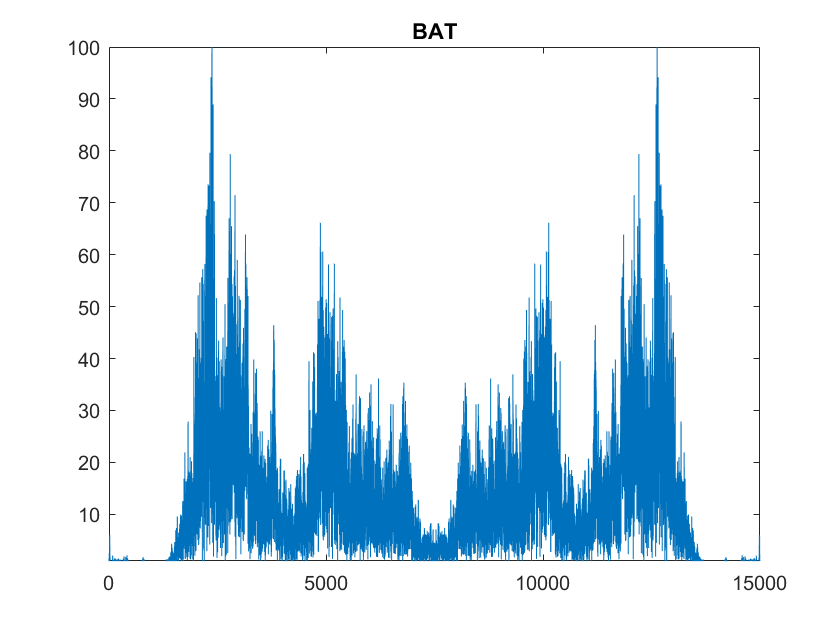

plot(Y2);
ylim([1,100]);
title("BAT");

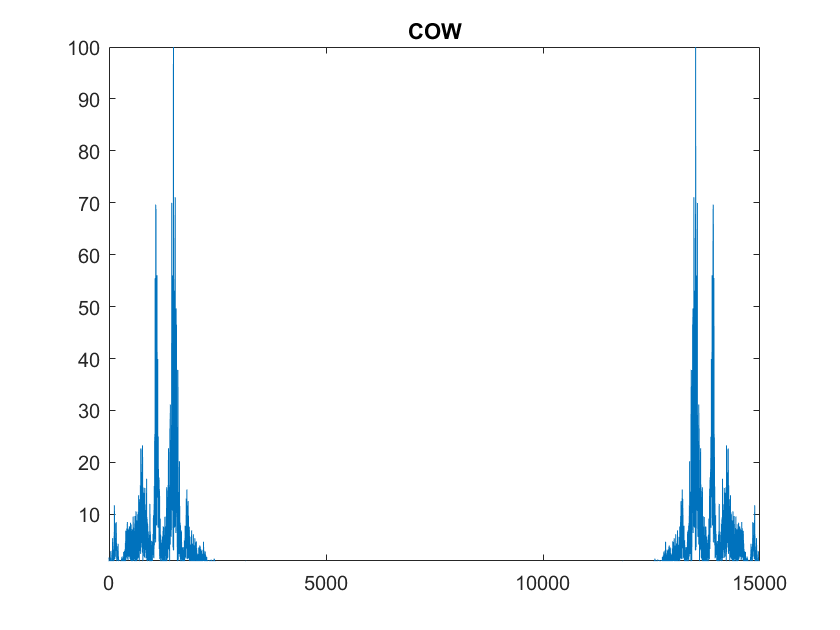

plot(Y3);
ylim([1,100]);
title("COW");

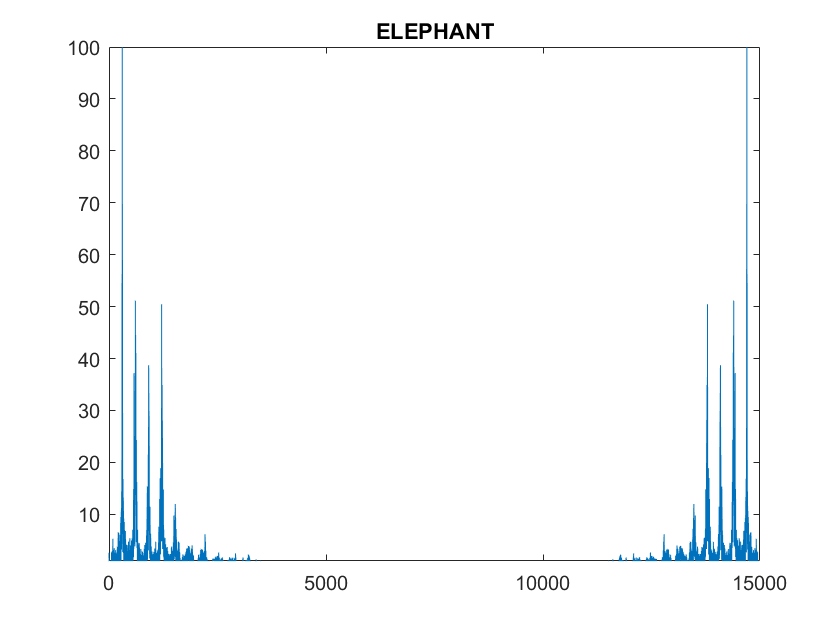

plot(Y4);
ylim([1,100]);
title("ELEPHANT");

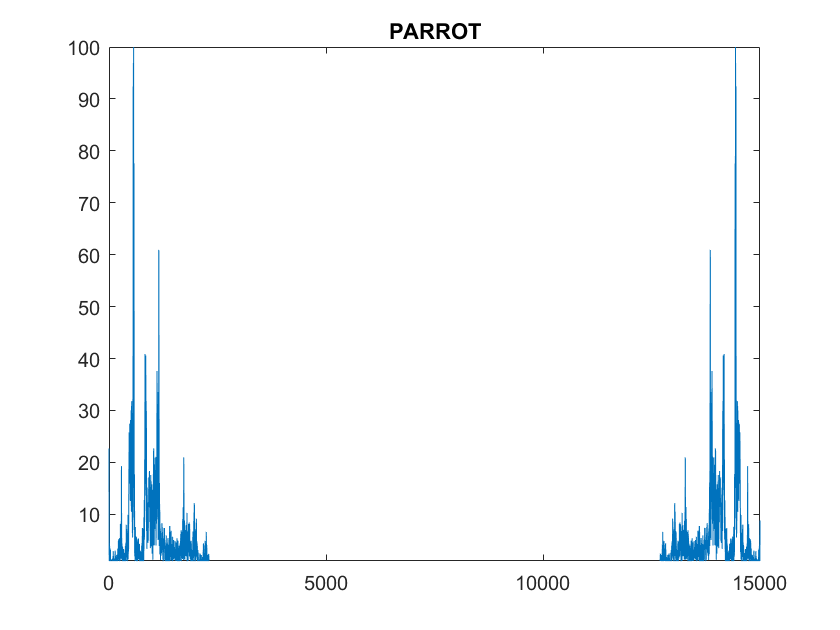

plot(Y5);
ylim([1,100]);
title("PARROT");

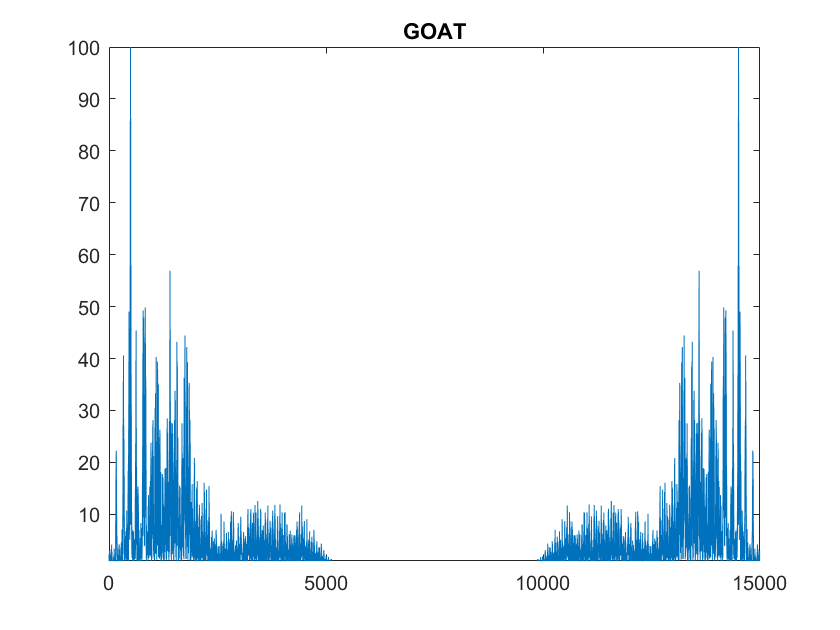

plot(Y6);
ylim([1,100]);
title("GOAT");

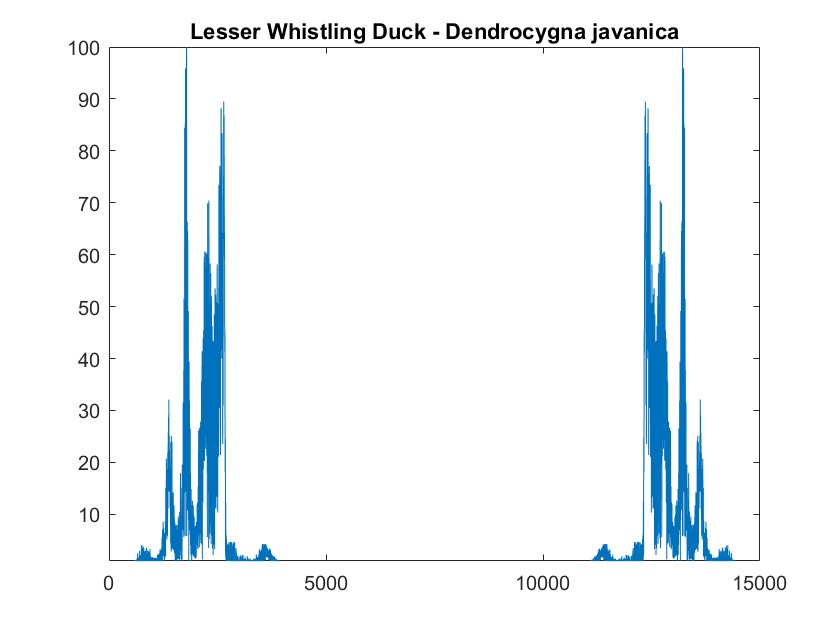

plot(Y7);
ylim([1,100]);
title("Lesser Whistling Duck - Dendrocygna javanica");

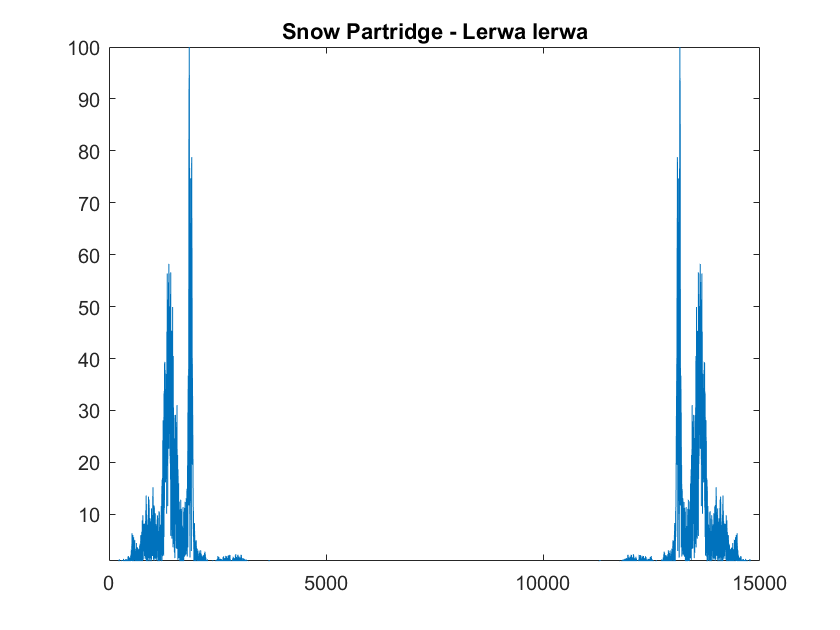

plot(Y8);
ylim([1,100]);
title("Snow Partridge - Lerwa lerwa");


%ref2(:, 1)
[corr_seq1 lags1] =xcorr(Y1,Y_in);
corr_seq1(lags1==0)

ans = 1.8618e+04

a=corr_seq1(lags1==0);
%max(corr_seq);

[corr_seq2 lags2] =xcorr(Y2,Y_in);
corr_seq2(lags2==0)

ans = 6.0950e+03

b=corr_seq2(lags2==0);
%max(corr_seq)

[corr_seq3 lags3] =xcorr(Y3,Y_in);
corr_seq3(lags3==0)

ans = 6.6719e+03

c=corr_seq3(lags3==0);
%max(corr_seq)


[corr_seq4 lags4] =xcorr(Y4,Y_in);
corr_seq4(lags4==0)

ans = 3.0435e+03

d=corr_seq4(lags4==0);
%max(corr_seq)

[corr_seq5 lags5] =xcorr(Y5,Y_in);
corr_seq5(lags5==0)

ans = 8.5965e+03

e=corr_seq5(lags5==0);
%max(corr_seq)

[corr_seq6 lags6] =xcorr(Y6,Y_in);
corr_seq6(lags6==0)

ans = 1.0990e+04

f=corr_seq6(lags6==0);

[corr_seq7 lags7] =xcorr(Y7,Y_in);
corr_seq7(lags7==0)

ans = 4.0641e+03

g=corr_seq7(lags7==0);

[corr_seq8 lags8] =xcorr(Y8,Y_in);
corr_seq8(lags8==0)

ans = 4.8007e+03

h=corr_seq8(lags8==0);
%max(corr_seq)

ans=[a,b,c,d,e,f,g,h];
max_val=max(ans)

max_val = 1.8618e+04


if(max_val==a)
    display("the bird species is  Bar-headed Goose - Anser indicus");
end

    "the bird species is  Bar-headed Goose - Anser indicus"



if(max_val==b)
    display("the animal is a bat");
end
if(max_val==c)
    display("the animal is a cow");
end
if(max_val==d)
    display("the animal is an elephant");
end
if(max_val==e)
    display("the animal is a parrot");
end
if(max_val==f)
    display("the animal is a goat");
end
if(max_val==g)
    display("the bird species is Lesser Whistling Duck - Dendrocygna javanica ");
end
if(max_val==h)
    display("the bird species is Snow Partridge - Lerwa lerwa ");
end

%ans= max(all answers)
